downs = grabFromFilter('DOWN Cells');
ups = grabFromFilter('UP Cells');

%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_SP10'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'Extracellular', '_ff'};
cantHave_1 = [];
cantHave_2 = {'Cesium', 'Intracellular', 'Potassium'}; %avoid anything with these tags
rigMandates = []; %no rig mandates

upPDs = [];
upCoords = zeros(0, 2);
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end    
    
    try
        [x, y] =  pol2cart(struct_i.coordinates.polar(1), struct_i.coordinates.polar(2));
        upCoords = [upCoords; x, y];
    catch
        disp(struct_i.cellID)
        continue
    end
    PD = mod(loc.Analysis_Results.PreferredDirection, 360);
    upPDs = [upPDs; PD];
    
end

SHOKR58Lc7


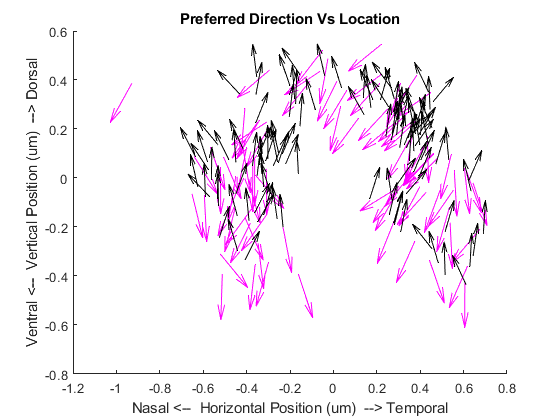


downPDs = [];
downCoords = zeros(0, 2);
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    
    
    try
        [x, y] =  pol2cart(struct_i.coordinates.polar(1), struct_i.coordinates.polar(2));
        downCoords = [downCoords; x, y];
    catch
        disp(struct_i.cellID)
        continue
    end
    
    PD = mod(loc.Analysis_Results.PreferredDirection, 360);
    downPDs = [downPDs; PD];
    
end


xCoords_up = upCoords(:, 1);
yCoords_up = upCoords(: , 2);

xCoords_down = downCoords(:, 1);
yCoords_down = downCoords(: , 2);

thetaDown = deg2rad(downPDs);
thetaUp = deg2rad(upPDs);
arrowLength = 0.1;

figure
title('Preferred Direction Vs Location')
hold on
quiver(-xCoords_down, yCoords_down, arrowLength*cos(thetaDown), arrowLength*sin(thetaDown), '-m', 'LineWidth', 1)
quiver(-xCoords_up, yCoords_up, arrowLength*cos(thetaUp), arrowLength*sin(thetaUp), '-k', 'LineWidth', 1)
xlabel('Nasal <--  Horizontal Position (um)  --> Temporal')
ylabel('Ventral <--  Vertical Position (um)  --> Dorsal')